# Data preparation: cleaning

The data in "biopsies_raw.csv" has not been cleaned:

clear all;
data = readtable('biopsies_raw.csv');

Clean the data and split it ready for training and testing a classifier.

Marks are available for:

- Appropriately addressing: duplicated examples; irrelevant features; missing values [5 marks]

- Identifying and removing the extreme outlier for the "smoothness_mean" feature [3 marks]

- Splitting the data up into an appropriately named training dataset and testing dataset [8 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

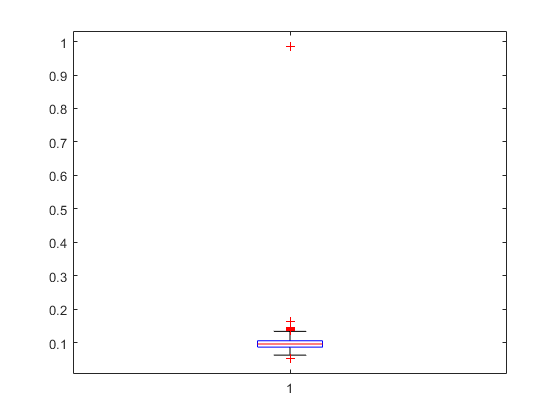

%clean missing values from table
data=rmmissing(data);
%remove duplicated examples
data=unique(data);
%remove irrelevant features
data(:,"id")=[];

%identify extreme outiler
boxplot(data{:,"smoothness_mean"});

%remove the extreme outiler
data(149,:)=[];

%splitting up the data
% 20% examples needed for testing
nTest=round(0.20*size(data,1))

nTest = 113

% shuffle the data
rng(1);
data_shuffled=data(randperm(size(data,1)),:);
%split the data 
data_test=data_shuffled(1:1:nTest,:);
data_train=data_shuffled(nTest+1:1:end,:);
%separating the class labels
test_labels=categorical(data_test{:,"diagnosis"});
test_examples=data_test;
test_examples(:,'diagnosis')=[];

train_labels=categorical(data_train{:,"diagnosis"});
train_examples=data_train;
train_examples(:,'diagnosis')=[];